# Temperature - Regression

## 1.

Load the data stored in the file `TemperatureData.mat`.

load TemperatureData

## 2.

Create a new variable `time` by shifting the `dates` vector to start at zero and transform it into units of days.

time = days(dates-dates(1))

time = 	1.0e+03 *

         0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0004


## 3.

Define a nonlinear model consisting of a linear trend, a yearly sinusoidal wave (with unknown amplitude and offset in time), and daily sinusoidal wave (with unknown amplitude and offset in time). The model function is of the form


$$T(b,t) = b_1 + b_2t+b_3\sin\left(\frac{2\pi}{365}t+b_4\right) + b_5\sin\left(2\pi t + b_6\right)$$


model = @(b,t) b(1) + b(2)*t + ...
    b(3)*sin(2*pi*t/365 + b(4)) + ...
    b(5)*sin(2*pi*t + b(6))

model = function_handle with value:
    @(b,t)b(1)+b(2)*t+b(3)*sin(2*pi*t/365+b(4))+b(5)*sin(2*pi*t+b(6))

## 4.

Determine good initial guesses for the six unknown parameters `b_1` to `b_6`.

b0 = [10; 0; 15; -pi/2; 5; -pi/2]

b0 =    10.0000
         0
   15.0000
   -1.5708
    5.0000
   -1.5708


## 5.

Perform a nonlinear regression to determine the parameters `b_1` to `b_6`.

tempFit = fitnlm(time,degCelsius, model, b0)

tempFit = Nonlinear regression model:
    y ~ b1 + b2*t + b3*sin(2*pi*t/365 + b4) + b5*sin(2*pi*t + b6)

Estimated Coefficients:
           Estimate         SE          tStat       pValue 
          __________    __________    __________    _______
    b1        9.9396       0.03881        256.11          0
    b2    2.1341e-08    3.0732e-05    0.00069442    0.99945
    b3        12.663      0.027297         463.9          0
    b4       -1.9947     0.0021696       -919.41          0
    b5        3.1703      0.027269        116.26          0
    b6       -2.4928     0.0086013       -289.81          0

Number of observations: 52608, Error degrees of freedom: 52602
Root Mean Squared Error: 4.42
R-Squared: 0.813,  Adjusted R-Squared 0.813
F-statistic vs.

## 6.

Evaluate the fitted model and plot it together with the original data on the same set of axes.

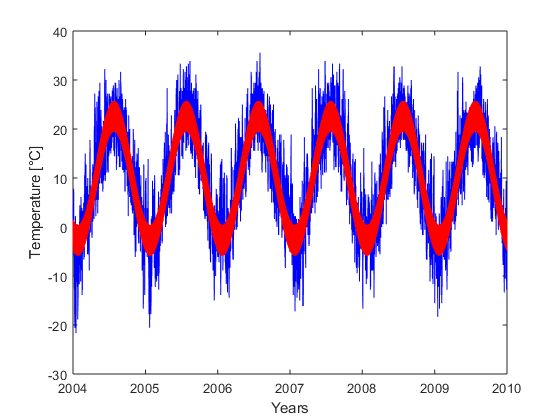

tempModel = predict(tempFit,time);
plot(dates,degCelsius,'b',dates,tempModel,'r');
datetick
xlabel('Years')
ylabel('Temperature [°C]')

## BONUS:

Try to identify the distribution of the residuals.

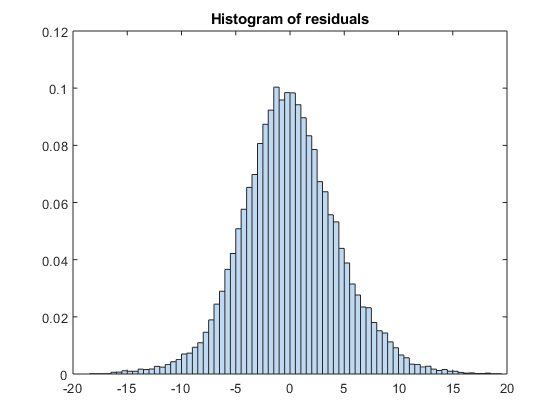

tempResiduals = tempFit.Residuals.Raw;
plotResiduals(tempFit)

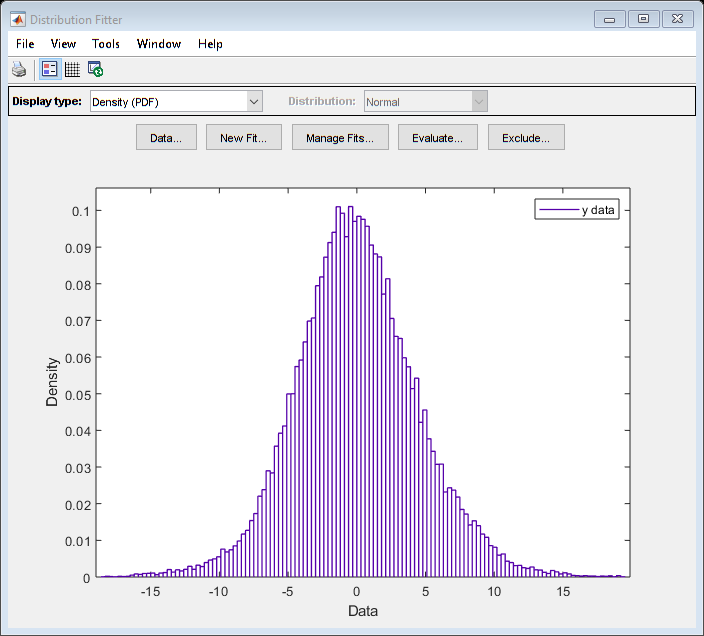

dfittool(tempResiduals)